IPR_st.name='IPR'; 
IPR_st.lat=45.8;
IPR_st.lon=8.633;
IPR_st.alt=209;
IPR_st.env='con';
IPR_st.footp='U'

IPR_st = struct with fields:
     name: 'IPR'
      lat: 45.8000
      lon: 8.6330
      alt: 209
      env: 'con'
    footp: 'U'


IPR_rd=read_betsy('IPR_2004_2017',IPR_st.name);
IPR_rdN=read_betsy('IPR_2004_2017_incl_aeth',IPR_st.name);

datevec(IPR_rd.Time(1))

ans =         2004           1           2           0           0           0

datevec(IPR_rd.Time(end))

ans =         2018           1           1           0           0           0

prctile(IPR_rd.U_S,[5 50 95])

ans =     6.1400   24.3000   56.2500

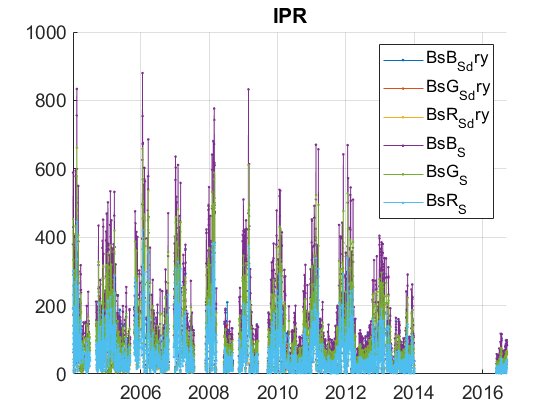

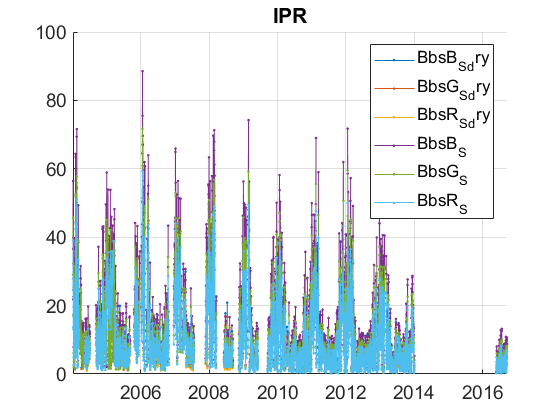

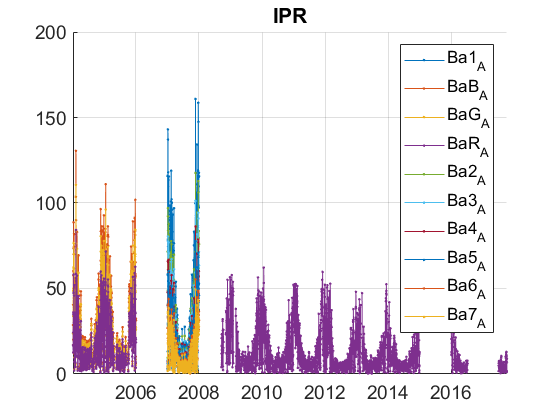

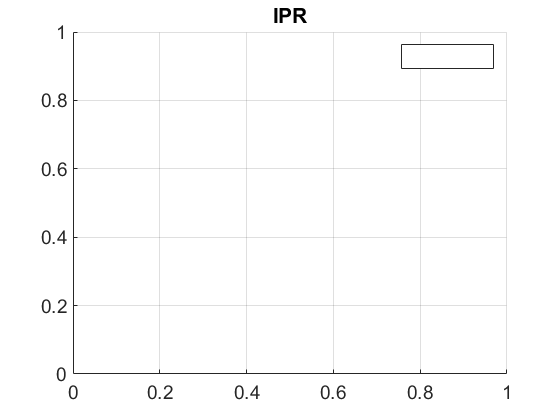

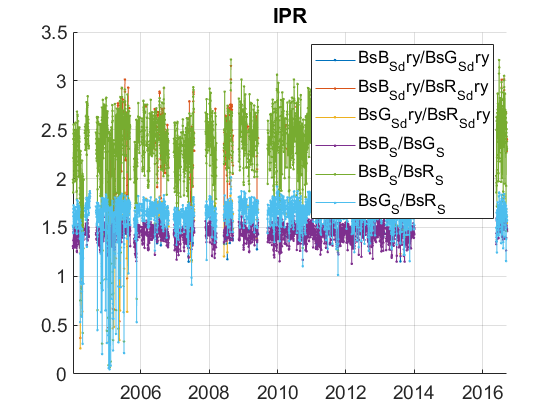

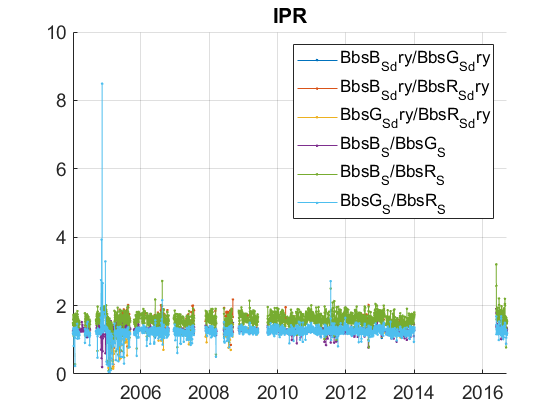

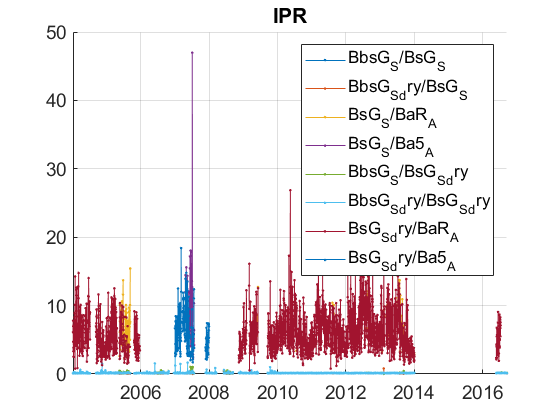

plotFigControl(IPR_rd,IPR_st.name);

plotFigControl(IPR_rdN,IPR_st.name);
% 1 size cut, ok
% sc: ok, max in summer, no negatives
% abs: 2 size cut, max in summer, no negatives


lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
IPR_cal=compute_exp_SSA(IPR_rd,lambdaSC, lambdaAE);

SCexclus = 0

ans = 0

ans = 4759

ans = 0

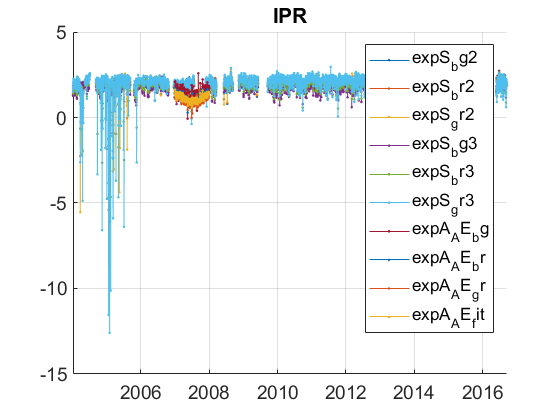

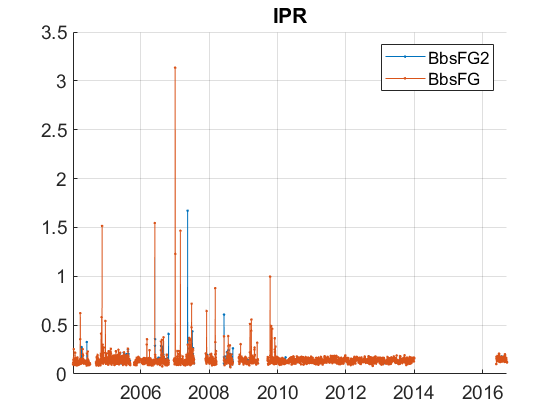

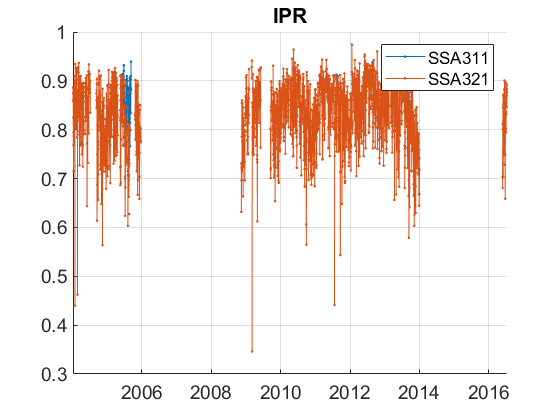

plotFigControl_cal(IPR_cal,IPR_st.name);

PBC1=retime('2009-01-01','2010-01-01');
PBC2=retime('2014-01-01','2015-01-01');
names=fieldnames(IPR_rdN);
c=contains(names,'A14')==1 & startsWith(names,'Ba1')==0;
N=names(c);
IPR_rdN
plotFigControl(IPR_rdN,IPR_st.name);
IPR_calN=compute_exp_SSA(IPR_rdN,lambdaSC, lambdaAE);
plotFigControl_cal(IPR_calN,IPR_st.name);



%Questions:
%problems:
%sc: 2014, 15 and 17 missing   
% %MAAP=: 2006 ,2007, 2008 and 2015 missing + part of 2016 and 2017, 
% AE: only 2007
%re-submission expected but not all were mentionned


%2015: prendre fichier envoyés

t=datenum([2015 01 01 00 00 00])*ones(8760,1)+IT0004R.VarName1;
abs15=timetable(datetime (datevec(t)));
abs15.Ba1_A14=IT0004R.VarName5;
abs15.Ba2_A14=IT0004R.VarName6;
abs15.Ba3_A14=IT0004R.VarName7;
abs15.Ba4_A14=IT0004R.VarName8;
abs15.Ba5_A14=IT0004R.VarName9;
abs15.Ba6_A14=IT0004R.VarName10;
abs15.Ba7_A14=IT0004R.VarName11;
%abs15.flag=IT0004R.VarName26; tous les flags valides
%mediane
abs15=retime(abs15,'daily',@nanmedian);

IPR_tr=IPR_rdN; 
IPR_tr.y=year(IPR_tr.Time);
% begin at the beginning of a year: 2004
%end 2017
P=timerange('2004-01-01','2018-01-01');
IPR_tr=IPR_tr(P,:);

%  trend in U and dry
names=fieldnames(IPR_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"flag"]) | contains(names,'Q');
N=names(c);
for i=1:length(N)
    IPR_tr.(N{i})=[];
end

%do one time series with nephelometers S11 and S12 (there is always 2
%instruments), also for U
%fragmentation issue due to size cut: seems to be TSP and then 2 size cuts. Do one time seris TSP-PM10
IPR_tr.BsB_S11=sum([IPR_tr.BsB_S11 IPR_tr.BsB_S12],2,'omitnan');
indz=IPR_tr.BsB_S11==0;
IPR_tr.BsB_S11(indz)=NaN;
IPR_tr.BsG_S11=sum([IPR_tr.BsG_S11 IPR_tr.BsG_S12],2,'omitnan');
indz=IPR_tr.BsG_S11==0;
IPR_tr.BsG_S11(indz)=NaN;
IPR_tr.BsR_S11=sum([IPR_tr.BsR_S11 IPR_tr.BsR_S12],2,'omitnan');
indz=IPR_tr.BsR_S11==0;
IPR_tr.BsR_S11(indz)=NaN;

IPR_tr.BbsB_S11=sum([IPR_tr.BbsB_S11 IPR_tr.BbsB_S12],2,'omitnan');
indz=IPR_tr.BbsB_S11==0;
IPR_tr.BbsB_S11(indz)=NaN;
IPR_tr.BbsG_S11=sum([IPR_tr.BbsG_S11 IPR_tr.BbsG_S12],2,'omitnan');
indz=IPR_tr.BbsG_S11==0;
IPR_tr.BbsG_S11(indz)=NaN;
IPR_tr.BbsR_S11=sum([IPR_tr.BbsR_S11 IPR_tr.BbsR_S12],2,'omitnan');
indz=IPR_tr.BbsR_S11==0;
IPR_tr.BbsR_S11(indz)=NaN;

IPR_tr.BsB_S11_dry=sum([IPR_tr.BsB_S11_dry IPR_tr.BsB_S12_dry],2,'omitnan');
indz=IPR_tr.BsB_S11_dry==0;
IPR_tr.BsB_S11_dry(indz)=NaN;
IPR_tr.BsG_S11_dry=sum([IPR_tr.BsG_S11_dry IPR_tr.BsG_S12_dry],2,'omitnan');
indz=IPR_tr.BsG_S11_dry==0;
IPR_tr.BsG_S11_dry(indz)=NaN;
IPR_tr.BsR_S11_dry=sum([IPR_tr.BsR_S11_dry IPR_tr.BsR_S12_dry],2,'omitnan');
indz=IPR_tr.BsR_S11_dry==0;
IPR_tr.BsR_S11_dry(indz)=NaN;

IPR_tr.BbsB_S11_dry=sum([IPR_tr.BbsB_S11_dry IPR_tr.BbsB_S12_dry],2,'omitnan');
indz=IPR_tr.BbsB_S11_dry==0;
IPR_tr.BbsB_S11_dry(indz)=NaN;
IPR_tr.BbsG_S11_dry=sum([IPR_tr.BbsG_S11_dry IPR_tr.BbsG_S12_dry],2,'omitnan');
indz=IPR_tr.BbsG_S11_dry==0;
IPR_tr.BbsG_S11_dry(indz)=NaN;
IPR_tr.BbsR_S11_dry=sum([IPR_tr.BbsR_S11_dry IPR_tr.BbsR_S12_dry],2,'omitnan');
indz=IPR_tr.BbsR_S11_dry==0;
IPR_tr.BbsR_S11_dry(indz)=NaN;

IPR_tr.U_S11=sum([IPR_tr.U_S11 IPR_tr.U_S12],2,'omitnan');
indz=IPR_tr.U_S11==0;
IPR_tr.U_S11(indz)=NaN;

%delete S12
names=fieldnames(IPR_tr);
c=contains(names,'S12');
N=names(c);
for i=1:length(N)
    IPR_tr.(N{i})=[];
end
% abs: use AE, delete BaR_A11 and A12, too short
c=contains(names,'BaR');
N=names(c);
for i=1:length(N)
    IPR_tr.(N{i})=[];
end

%2014: divisé par 1e3 %2006 prendre A14 divisé par 1e3
P1=timerange('2006-01-01','2007-01-01');
P2=timerange('2014-01-01','2015-01-01');
names=fieldnames(IPR_tr);
c=contains(names,'A14');
N=names(c);
for i=1:length(N)
    IPR_tr.(N{i})(P1)= IPR_tr.(N{i})(P1)./1e3;
      IPR_tr.(N{i})(P2)= IPR_tr.(N{i})(P2)./1e3;
end
% % % prend les donnees 2015 du fichier abs15
% % P2=timerange('2015-01-01','2016-01-01');
% % IPR_tr.Ba1_A14(P2)=abs15.Ba1_A14;
% % IPR_tr.Ba2_A14(P2)=abs15.Ba2_A14;
% % IPR_tr.Ba3_A14(P2)=abs15.Ba3_A14;
% % IPR_tr.Ba4_A14(P2)=abs15.Ba4_A14;
% % IPR_tr.Ba5_A14(P2)=abs15.Ba5_A14;
% % IPR_tr.Ba6_A14(P2)=abs15.Ba6_A14;
% % IPR_tr.Ba7_A14(P2)=abs15.Ba7_A14;

% prend les donnees 2015 du fichier abs15
P2=timerange('2015-01-01','2016-01-01');
IPR_tr.Ba1_A13(P2)=abs15.Ba1_A14;
IPR_tr.Ba2_A13(P2)=abs15.Ba2_A14;
IPR_tr.Ba3_A13(P2)=abs15.Ba3_A14;
IPR_tr.Ba4_A13(P2)=abs15.Ba4_A14;
IPR_tr.Ba5_A13(P2)=abs15.Ba5_A14;
IPR_tr.Ba6_A13(P2)=abs15.Ba6_A14;
IPR_tr.Ba7_A13(P2)=abs15.Ba7_A14;

% 25 jullet 2012-8 jan 2013: take A14, no A13
P4=timerange('2012-07-25','2013-01-08');
IPR_tr.Ba1_A13(P4)=IPR_tr.Ba1_A14(P4);
IPR_tr.Ba2_A13(P4)=IPR_tr.Ba2_A14(P4);
IPR_tr.Ba3_A13(P4)=IPR_tr.Ba3_A14(P4);
IPR_tr.Ba4_A13(P4)=IPR_tr.Ba4_A14(P4);
IPR_tr.Ba5_A13(P4)=IPR_tr.Ba5_A14(P4);
IPR_tr.Ba6_A13(P4)=IPR_tr.Ba6_A14(P4);
IPR_tr.Ba7_A13(P4)=IPR_tr.Ba7_A14(P4);

% 2006: take A14, no A13
P6=timerange('2006-01-01','2007-01-01');
IPR_tr.Ba1_A13(P6)=IPR_tr.Ba1_A14(P6);
IPR_tr.Ba2_A13(P6)=IPR_tr.Ba2_A14(P6);
IPR_tr.Ba3_A13(P6)=IPR_tr.Ba3_A14(P6);
IPR_tr.Ba4_A13(P6)=IPR_tr.Ba4_A14(P6);
IPR_tr.Ba5_A13(P6)=IPR_tr.Ba5_A14(P6);
IPR_tr.Ba6_A13(P6)=IPR_tr.Ba6_A14(P6);
IPR_tr.Ba7_A13(P6)=IPR_tr.Ba7_A14(P6);

% % % 9.6.2017-23.9.2017: take A13, no A14
% % P5=timerange('2017-06-09','2017-09-23');
% % IPR_tr.Ba1_A14(P5)=IPR_tr.Ba1_A13(P5);
% % IPR_tr.Ba2_A14(P5)=IPR_tr.Ba2_A13(P5);
% % IPR_tr.Ba3_A14(P5)=IPR_tr.Ba3_A13(P5);
% % IPR_tr.Ba4_A14(P5)=IPR_tr.Ba4_A13(P5);
% % IPR_tr.Ba5_A14(P5)=IPR_tr.Ba5_A13(P5);
% % IPR_tr.Ba6_A14(P5)=IPR_tr.Ba6_A13(P5);
% % IPR_tr.Ba7_A14(P5)=IPR_tr.Ba7_A13(P5);

% 8.10.2017-31.12.2017: take A14, no A13
P5=timerange('2017-10-08','2018-01-01');
IPR_tr.Ba1_A13(P5)=IPR_tr.Ba1_A14(P5);
IPR_tr.Ba2_A13(P5)=IPR_tr.Ba2_A14(P5);
IPR_tr.Ba3_A13(P5)=IPR_tr.Ba3_A14(P5);
IPR_tr.Ba4_A13(P5)=IPR_tr.Ba4_A14(P5);
IPR_tr.Ba5_A13(P5)=IPR_tr.Ba5_A14(P5);
IPR_tr.Ba6_A13(P5)=IPR_tr.Ba6_A14(P5);
IPR_tr.Ba7_A13(P5)=IPR_tr.Ba7_A14(P5);

% % % prendre le plus récent en 2014: A14 
% % P3=timerange('2015-01-01','2018-01-01');
% % IPR_tr.Ba1_A13(P3)=IPR_tr.Ba1_A14(P3);
% % IPR_tr.Ba2_A13(P3)=IPR_tr.Ba2_A14(P3);
% % IPR_tr.Ba3_A13(P3)=IPR_tr.Ba3_A14(P3);
% % IPR_tr.Ba4_A13(P3)=IPR_tr.Ba4_A14(P3);
% % IPR_tr.Ba5_A13(P3)=IPR_tr.Ba5_A14(P3);
% % IPR_tr.Ba6_A13(P3)=IPR_tr.Ba6_A14(P3);
% % IPR_tr.Ba7_A13(P3)=IPR_tr.Ba7_A14(P3);

%delete A_14
names=fieldnames(IPR_tr);
c=contains(names,'A14');
N=names(c);
for i=1:length(N)
    IPR_tr.(N{i})= [];
end

% A_13 > 999= NaN;
names=fieldnames(IPR_tr);
c=contains(names,'A13');
N=names(c);
for i=1:length(N)
    IPR_tr.(N{i})(IPR_tr.(N{i})>499)= NaN;
end
% plotFigControl(IPR_tr,IPR_st.name);
%IPR_cal2=compute_exp_SSA(IPR_tr,lambdaSC, lambdaAE);
IPR_cal2=timetable(IPR_tr.Time);
%compute expS on GR
IPR_cal2.expS_gr=real(-log(IPR_tr.BsG_S11./IPR_tr.BsR_S11)/log(lambdaSC(2)/lambdaSC(3)));
IPR_cal2.expS_gr_dry=real(-log(IPR_tr.BsG_S11_dry./IPR_tr.BsR_S11_dry)/log(lambdaSC(2)/lambdaSC(3)));
%compute BbsFR (problem on G in 2017)
IPR_cal2.BbsFR=IPR_tr.BbsR_S11./IPR_tr.BsR_S11;
IPR_cal2.BbsFR_dry=IPR_tr.BbsR_S11_dry./IPR_tr.BsR_S11_dry;
%compute SSA with G and 3
IPR_cal2.SSAG=IPR_tr.BsG_S11./(IPR_tr.BsG_S11+IPR_tr.Ba3_A13);
% IPR_cal2.SSAB=IPR_tr.BsB_S11./(IPR_tr.BsB_S11+IPR_tr.Ba2_A13);
% IPR_cal2.SSAR=IPR_tr.BsR_S11./(IPR_tr.BsR_S11+IPR_tr.Ba5_A13);
IPR_cal2.SSAG_dry=IPR_tr.BsG_S11_dry./(IPR_tr.BsG_S11_dry+IPR_tr.Ba3_A13);
%compute expA with 2-3, 2-4, 2-5,4-5
%IPR_cal2.expA_23=real(-log(IPR_tr.Ba2_A13./IPR_tr.Ba3_A13)/log(lambdaAE7(2)/lambdaAE7(3)));
IPR_cal2.expA_35=real(-log(IPR_tr.Ba3_A13./IPR_tr.Ba5_A13)/log(lambdaAE7(3)/lambdaAE7(5)));
%IPR_cal2.expA_25=real(-log(IPR_tr.Ba2_A13./IPR_tr.Ba5_A13)/log(lambdaAE7(2)/lambdaAE7(5)));
% all_Abs=[IPR_tr.Ba1_A13 IPR_tr.Ba2_A13 IPR_tr.Ba3_A13 IPR_tr.Ba4_A13 IPR_tr.Ba5_A13 IPR_tr.Ba6_A13 IPR_tr.Ba7_A13];
        %IPR_cal2.expA_fit=Exp_AE_nan_regr(all_Abs);
% 
IPR_tr=outerjoin(IPR_tr, IPR_cal2);

%compute trendonly on G
%compute trend only on green
IPR_tr.BsB_S11=[];
IPR_tr.BsB_S11_dry=[];
IPR_tr.BsR_S11=[];
IPR_tr.BsR_S11_dry=[];
IPR_tr.BbsB_S11=[];
IPR_tr.BbsB_S11_dry=[];
IPR_tr.BbsR_S11=[];
IPR_tr.BbsR_S11_dry=[];

IPR_tr.Ba1_A13=[];
IPR_tr.Ba2_A13=[];
IPR_tr.Ba4_A13=[];
IPR_tr.Ba5_A13=[];
IPR_tr.Ba6_A13=[];
IPR_tr.Ba7_A13=[];

IPR_result= all_trend_STN(IPR_tr,IPR_st); 
plot_10y_in_two(IPR_result, IPR_st);

IPR_result_D=IPR_result;